clear; clc; close all;

% Constants
alpha = 1.476; % Schwarzschild radius per solar mass (km)
beta = 0.03778; % Density scaling factor (km^-3)
Anr = 2.4216; 
Ar = 2.8663; 
n = 5.0 / 3.0; % Polytropic index

% Range of central pressures (adjusted for smoother curve)
p0_vals = logspace(-30, 0, 300); % Increased to 200 points for better resolution

% Storage for mass-radius values
M_vals = [];
R_vals = [];

% Define ODE options for better accuracy
options = odeset('RelTol',1e-10, 'AbsTol',1e-10);

% Function for TOV equations
function dydr = tov_eqs(r, y, alpha, beta, n, Anr, Ar)
    p = y(1); % Pressure
    m = y(2); % Mass
    E = Anr * (p^(1/n)) + Ar * p; % Energy density

    % Avoid singularity
    if (1 - 2 * alpha * m / r) <= 0
        dydr = [0; 0];
        return;
    end

    dpdr = -alpha * E * (m + beta * r^3 * p) * (1 + p / E) / (r^2 * (1 - 2 * alpha * m / r));
    dmdr = beta * r^2 * E;
    dydr = [dpdr; dmdr];
end

% Loop over central pressures
for p0 = p0_vals
    % Solve ODE
    r_eval = linspace(1e-12,25,1000);
    [r, Y] = ode23s(@(r, y) tov_eqs(r, y, alpha, beta, n, Anr, Ar), r_eval, [p0; 0], options);
    
    p_vals = Y(:, 1);
    m_vals = Y(:, 2);
    
    % Find surface (p → 0)
    idx = find(p_vals <= 1e-50, 1);
    if ~isempty(idx)
        R_surface = r(idx);
        M_surface = m_vals(idx);
        
        if R_surface > 1e-10 && M_surface > 1e-10
            R_vals = [R_vals, R_surface];
            M_vals = [M_vals, M_surface];
        end
    end
end


% Ensure smooth ordering of points and remove duplicates
[R_vals, unique_idx] = unique(R_vals, 'stable'); % Remove duplicate radii
M_vals = M_vals(unique_idx);

% Sort by radius in ascending order
[R_vals, sort_idx] = sort(R_vals, 'ascend');
M_vals = M_vals(sort_idx);

% Determine maximum mass
[max_mass, idx] = max(M_vals);
max_radius = R_vals(idx);
fprintf('Maximum Mass: %f Solar Mass at Radius %f km\n', max_mass, max_radius);

Maximum Mass: 0.776359 Solar Mass at Radius 10.360360 km




% Plot results
figure;
hold on;
plot(R_vals, M_vals, 'b-', 'LineWidth', 2); % M-R curve

plot(max_radius, max_mass, 'ro', 'MarkerSize', 8, 'LineWidth', 2); % Max mass marker


% Draw vertical line from max mass to x-axis
line([max_radius, max_radius], [0, max_mass], ...
     'Color', 'r', 'LineStyle', '--', 'LineWidth', 1.5);

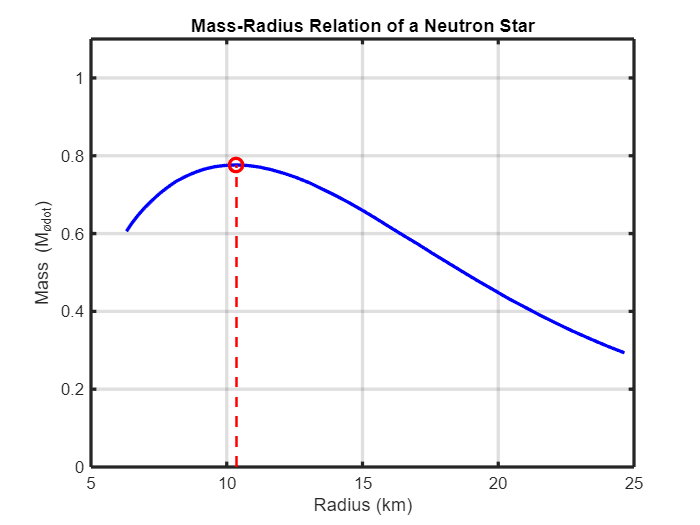


hold off;
box on;
% Labels and formatting
xlabel('Radius (km)');
ylabel('Mass (M_{\odot})');
title('Mass-Radius Relation of a Neutron Star');
set(gca, 'LineWidth', 2);
grid on;

% Adjust axis ranges
xlim([5, 25]);  
ylim([0, 1.1]);